# UAVのホバリング Part 1: PID制御とは

## フィードバック制御

「[はじめに](matlab:open('FOA_control.mlx'))」で示したフィードバック制御の復習であるが、フィードバック制御は、以下のFig.1のように構成される。

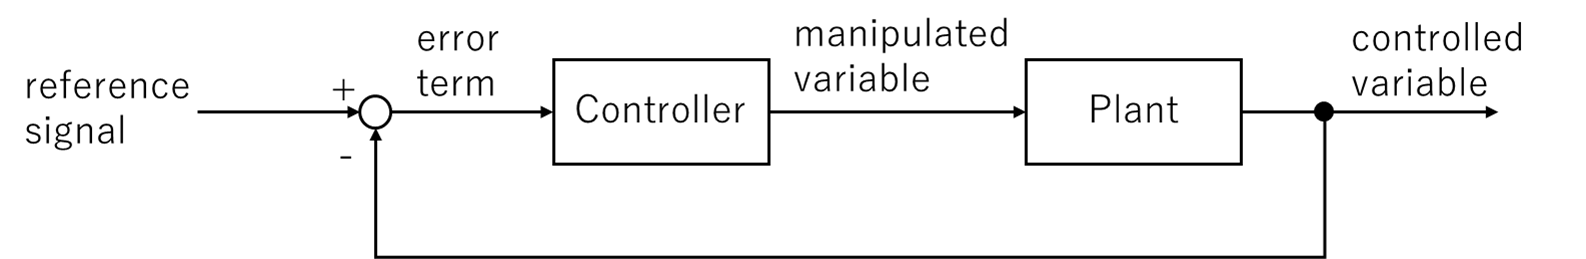

Fig.1 フィードバック制御

"Controller"は制御器、"Plant"は制御対象のシステムを意味し、プラントと呼ぶこともある。"reference signal"は指令値、"controlled variable"は制御量、"manipulated variable"は操作量、"error term"は指令値と制御量の差分である。制御器は、指令値と制御量の差分から、適切な操作量を計算してプラントに与え、指令値と制御量を一致させる操作を行う。

ここで、フィードバック制御の制御器として、「PID制御」が一般的に用いられる。PID制御は古典制御と呼ばれ、制御工学の歴史の最初期から存在しているが、現在においても、最も頻繁に用いられる制御器である。

## P制御

PID制御には様々な派生型が存在している。ここでは、PID制御の動作を理解するために、最も簡単な型である「比例(P)制御」について紹介する。例として、マルチコプター型UAVのホバリング制御について検討する。

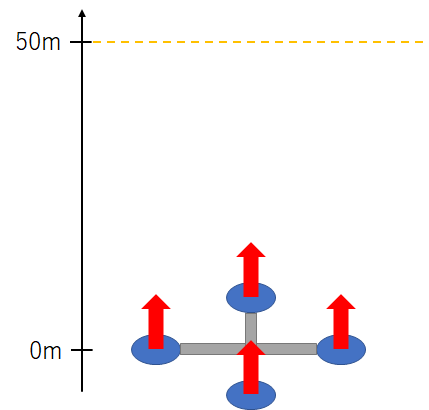

Fig.2 UAVのホバリング制御

Fig.2のように、地面に静止した状態から開始し、高さ50mまで上昇し、50m地点で高さ一定となるように制御を行う。

最適な操作をイメージすると、最初はプロペラを高速に回転させ、大きな推力を得て上昇を開始し、50m地点に近づくにつれて推力を落としていく、という操作が考えられる。この操作を実際に実現するため、比例制御を適用してみる。

UAVを制御する比例制御のモデルを'UHG_P_control.slx'に示す。以下のコマンドを実行して確認すること。

model_name = 'UHG_P_control';
open_system(model_name);

モデル内の'P_gain'というブロックは、指令値と制御量の差分を定数倍している。それを制御対象のシステムに渡す。このように、操作量が差分の比例となっていることから、比例制御と呼ばれている。'command'という信号は、プロペラ回転速度を意味する。今回はシンプルに、プロペラ回転速度に比例して推力（加速度）が発生するものとする。

モデルを実行して、結果を確認する。

sim(model_name);
UHG_P_control_plot_in_SDI;

今回のモデルは非常にシンプルに構築しているので、機体と地面との接触に関してはモデリングされていない点に注意すること。実行結果をFig.3に示す。

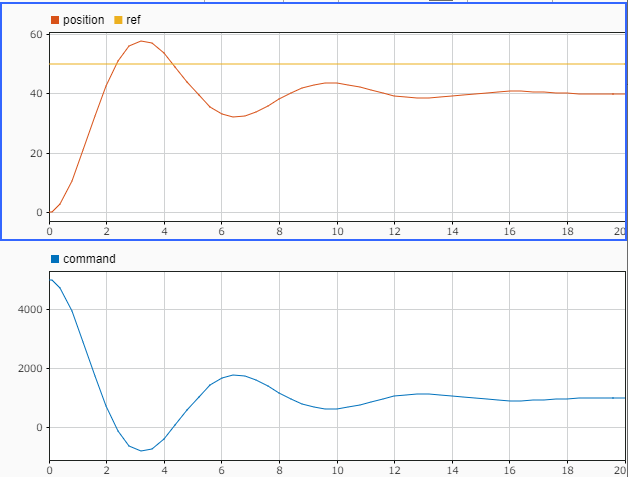

Fig. 3 比例制御の結果

制御開始時に最大の操作量（5000rpm）を出力し、50mに近づくにつれて減らす動きをしている。そして、振動しながらも、最終的には40m地点で定常状態に至っている。しかし、目標とする50m地点には到達していない。その理由はなぜだろうか。

UAVがホバリングをするためには、重力と等しい鉛直上向きの推力を出力する必要がある。その推力は、このモデルにおいては、100 * 9.8 = 980[rpm] である（モデルの'Plant_model'サブシステム内を確認すること）。比例制御器がこの数値を出力するためには、980 / 100 = 9.8 の入力が定常状態で必要になる（モデルの比例制御のゲインは100であるため）。従って、ホバリングするためには、9.8の差分（オフセット）が常に維持される必要がある。50 - 9.8 = 40.2[m] の位置でホバリングするのは、このためである。

50m地点でホバリングさせるためには、どうすれば良いだろうか。一つには、比例ゲインを大きくするという方法がある。

### Task 1

ここで、モデルの比例ゲインを200に設定し、シミュレーションを実行すること。

結果を確認すると、定常状態としては45m付近でホバリングしていることがわかる。上記の計算の流れを再度行えば、必要なオフセットは4.9である。よって、この高さでホバリングするのである。

制御目的が「50±6m以内でホバリングすること」であれば、これで目標を達成していることになるが、「±1m以内」の場合は、さらにゲインを高めなければならない。後述するが、極端に大きなゲインを設定することは危険であり、現実的に実行できない場合もある。そこで、このようなオフセットを無くすため、積分機能を付加した「比例積分(PI)制御」を導入する。

## PI制御

比例制御の比例ゲインに並行して積分器を付け足したものを、比例積分(PI)制御と呼ぶ。

モデル'UHG_PI_control.slx'に、PI制御を構成した。以下のコマンドを実行して確認すること。

model_name = 'UHG_PI_control';
open_system(model_name);

積分器は、差分に対して積分ゲインをかけた値を積分している。積分器と比例器の出力を加算した値を、最終的な操作量としている。

モデルを実行して、結果を確認する。

sim(model_name);
UHG_P_control_plot_in_SDI;

実行結果をFig.4に示す。

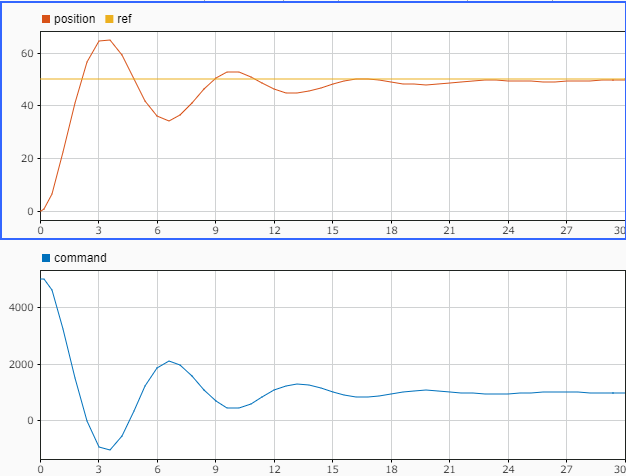

Fig.4 PI制御の結果

定常状態では、目標とする50m地点でホバリングできていることがわかる。

積分器は、プラスの入力が入ると出力を増やし、マイナスの入力が入ると出力を減らす作用を持つ。前節で説明した比例制御の動作により、定常的に10m程度の差分が発生した場合、積分器はその分、出力を増加させ続ける。その結果、徐々に差分は小さくなり、積分器も出力を増加させるペースを低下させていく。最終的に、高さは指令値と同じ50mとなるのである。

積分器は、入力が0であれば、その時点までに積分された値を出力し続ける。一方比例器は、入力が0であれば、0を出力する。従って、操作量が一定で定常状態になるためには、制御器の入力は0となっていなければならない。

### Task 2

モデルを開いて実行し、制御器の入力と積分器、比例器の出力がそのようになっていることを確認すること。

積分ゲインを増加させると、オフセットを0にする速度を早める効果を得る。モデルの'I_gain'を増加させ、応答の変化を確認すること。

一方で、積分ゲインを増加させていくと、振動が徐々に大きくなることがわかる。また、例えばゲインを50以上に設定したときには、システムが振動し続け、何秒経っても定常状態に至らない。このように、積分器にはシステムの不安定化を引き起こすデメリットが存在している。そこで、このデメリットを緩和させるため、微分機能を付加した「比例積分微分(PID)制御」を導入する。

## PID制御

比例積分制御の比例、積分に並行して微分器を付け足したものを、比例積分微分(PID)制御と呼ぶ。

モデル'UHG_PID_control.slx'に、PID制御を構成した。以下のコマンドを実行して確認すること。

model_name = 'UHG_PID_control';
open_system(model_name);

微分器は、差分に対して微分ゲインをかけた値を微分している。微分器、積分器、比例器の出力を加算した値を、最終的な操作量としている。

モデルを実行して、結果を確認する。

sim(model_name);
UHG_P_control_plot_in_SDI;

実行結果をFig.5に示す。

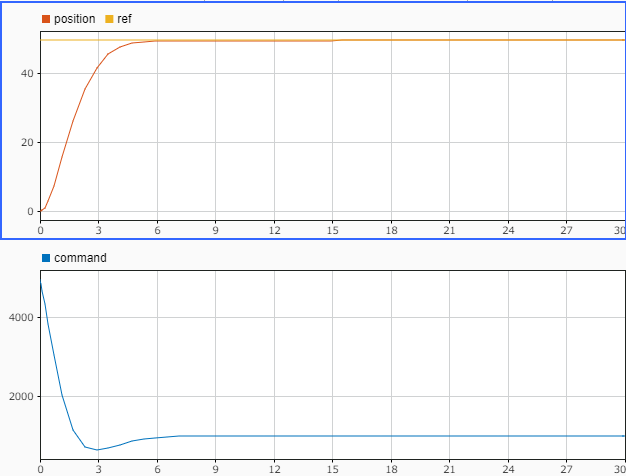

Fig.5 PID制御の結果

比例、積分ゲインは、'UHG_PI_control.slx'で最初に設定した値と同一である。微分器を導入した結果、振動が抑えられていることがわかる。

微分器は、入力の変化量がプラスのときにプラスの出力を、マイナスのときにマイナスの出力を行う。制御の開始直後は、比例器、積分器がプロペラ回転速度を増加させることで、偏差を小さくさせているが、その時、偏差の変化量はマイナスであるため、微分器はマイナスの値を出力する。この動作が積分器の過剰なプラス出力を打ち消すため、結果的にPID制御器の出力は抑えられ、システムを安定化させることができるのである。

### Task 3

微分ゲインを増減させ、モデルを再度実行して、微分器がどのような作用を及ぼしているか、確認すること。また、積分ゲイン、比例ゲインも変化させ、それぞれの比率によってどのような応答を示すのか、確認すること。

## PID制御器の選定

前節までで、PID制御器の導入背景と、その効果について説明した。その名前から、PID制御の比例器、積分器、微分器はセットで用いるものと思われがちであるが、実際は積分器、微分器は使わなくても制御目的を達成できる場合もある。

積分器は、定常状態のオフセットが無視できない場合に導入する。微分器は、P制御、またはPI制御の振動（過渡応答）が無視できない場合に導入する。そうでない場合は、必ずしも導入する必要はない。

[（はじめに）戻る](matlab:(proceed_live_page('FOA_control.mlx')))　|　[進む（Part 2: 積分器、微分器の拡張）](matlab:(proceed_live_page('UHG_control_UAV_p2.mlx')))

*Copyright 2021 The MathWorks, Inc.*